# Test Case - Motor Generator 1

mdl = "MotorGenerator1_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
MotorGenerator1_Component_harness_params

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters
simIn = setBlockParameter(simIn, mdl+"/Eng Trq Cmd", Before="100");
simIn = setBlockParameter(simIn, mdl+"/Eng Trq Cmd", Time="60");
simIn = setBlockParameter(simIn, mdl+"/Eng Trq Cmd", After="120");
simIn = setBlockParameter(simIn, mdl+"/MG1 Trq Cmd", Before="0");
simIn = setBlockParameter(simIn, mdl+"/MG1 Trq Cmd", Time="10");
simIn = setBlockParameter(simIn, mdl+"/MG1 Trq Cmd", After="-15");

% Initial conditions
simIn = setBlockParameter(simIn, mdl+"/Engine and Planetary/Engine Inertia", w="1500");

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "100");

% Run simulation
simOut = sim(simIn);

## Visualize Simulation Result

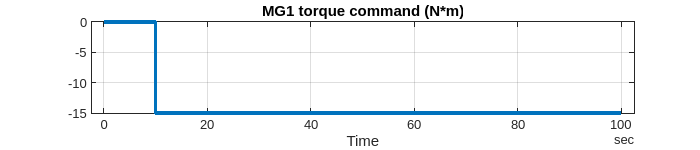

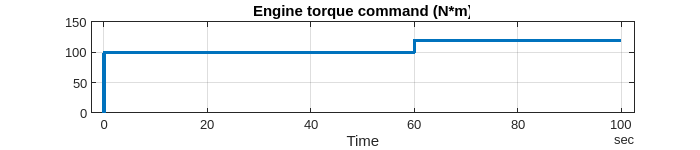

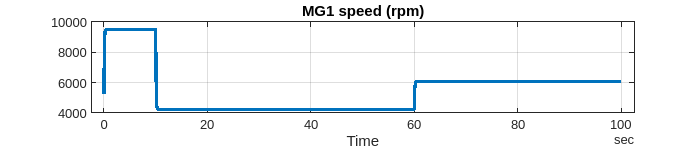

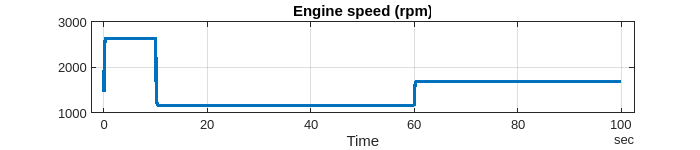

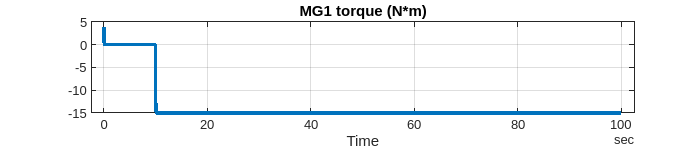

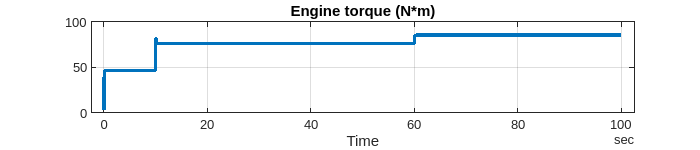

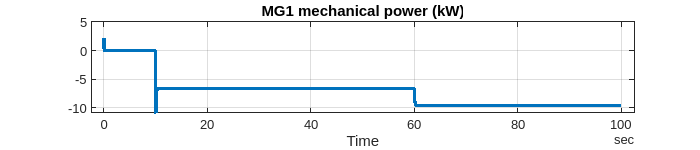

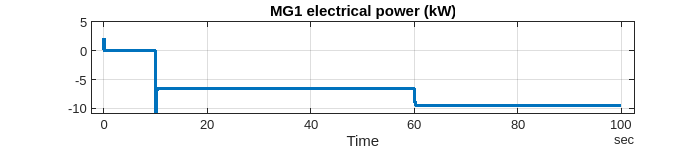

simData = extractTimetable(simOut.logsout);

sigNames = [ ...
  "MG1 torque command", ...
  "Engine torque command", ...
  "MG1 speed", ...
  "Engine speed", ...
  "MG1 torque", ...
  "Engine torque", ...
  "MG1 mechanical power", ...
  "MG1 electrical power", ...
  "Engine power", ...
  "Battery power" ];

for i = 1 : numel(sigNames)
  fig = MotorDriveUnit_plotResultSignal(SimData = simData, SignalName = sigNames(i));
  fig.Position(4) = 150;
end

*Copyright 2021-2022 The Mathworks, Inc.*